# **Second Optimal Control Project**

# **Designing a Discrete Infinite-Time LQR for a Linear 1/4-Car System**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

clear all;
close all;
clc

% System definition
A = [0 1 0 0;
     0 -0.14 -32 0.14;
     0 1 0 -1;
    -1562.5 1.0937 1812.5 -48.0312];

B = [0;
     0.0004;
     0;
    -0.0031];

C = [1 0 0 0;
     0 1 0 0;
     0 0 1 0];
D = zeros(size(C, 1), size(B, 2));

Ts = 0.01;
T = 60;
N = T/Ts;
sys = ss(A,B,C,D);
sysd = c2d(sys,Ts);
A = sysd.A;
B = sysd.B;
C = sysd.C;
D = sysd.D;

% Cost function matrices
Q = C'*C;
R = 1;
X0 = [0.2; 0.2; 0.2; 0.2];

[X,L,G] = dare(A,B,Q,R)

X = 1.0e+03 *

    6.7529    0.1528   -0.1000    0.0000
    0.1528    0.2424   -0.1735    0.0042
   -0.1000   -0.1735    0.1280   -0.0031
    0.0000    0.0042   -0.0031    0.0001


L =    0.9975 + 0.0524i
   0.9975 - 0.0524i
   0.7386 + 0.2712i
   0.7386 - 0.2712i


G = 1.0e-03 *

    0.4957    0.8351   -0.5994    0.0147


x(:,1) = X0;
for j = 1:N-1
u(:,j)= -G*x(:,j);
x(:,j+1) = A*x(:,j)+B*u(:,j);
y(:,j) = C*x(:,j);
end

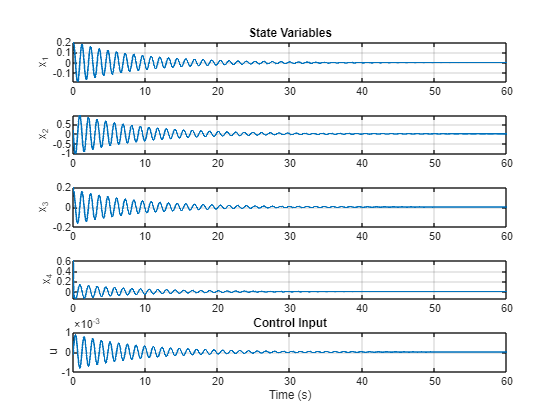

% Time vectors
t = Ts:Ts:T;       % N time steps for x
t_u = t(1:end-1);       % N-1 steps for u, y

% Plot all state variables
figure;
subplot(5,1,1);
plot(t, x(1,:), 'LineWidth', 1.2);
ylabel('x_1');
title('State Variables');
grid on;

subplot(5,1,2);
plot(t, x(2,:), 'LineWidth', 1.2);
ylabel('x_2');
grid on;

subplot(5,1,3);
plot(t, x(3,:), 'LineWidth', 1.2);
ylabel('x_3');
grid on;

subplot(5,1,4);
plot(t, x(4,:), 'LineWidth', 1.2);
ylabel('x_4');
grid on;

% Plot control input u
subplot(5,1,5);
plot(t_u, u(1,:), 'LineWidth', 1.2);
ylabel('u');
xlabel('Time (s)');
title('Control Input');
grid on;